clear s Data
s=serialport("/dev/ttyUSB0",115200,'Timeout',2)

s =   Serialport with properties:

                 Port: "/dev/ttyUSB0"
             BaudRate: 115200
    NumBytesAvailable: 0

  Show all properties, functions



data = readline(s)

data =     "0.00 ,0.0 ,0.0 ,0 ,0.0 ; 
     "


i=1;
while(~isempty(data))
    Data(i,:) = str2num(data); %#ok<ST2NM,SAGROW> 
    data = readline(s);
    i = i+1;
end

size(Data)

ans =         1992           5


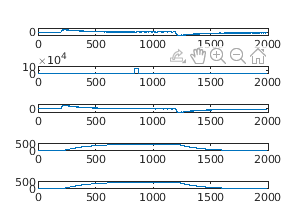


[m,n] = size(Data) ;
for i = 1:n
    subplot(n,1,i)
    plot(Data(:,i))
end


clear s